close all;
clc;
clear;

Code

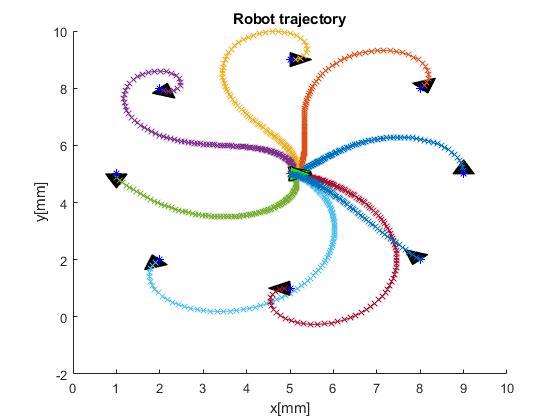

% TARGET
zheta_target = [5;5;0];
%INITIAL POSITIONS  pose (x, y, theta)
%1/8th of a circle
[x] = [9,8,5,2,1,2,5,8];
[y] = [5,8,9,8,5,2,1,2];
% Initial theta    
theta_init=[-pi/2,-3*pi/4,-pi,-5*pi/4,-3*pi/2,-7*pi/4,-2*pi,-pi/4];
zheta_init=[x;y;theta_init];
%plot initial positions and target
%  figure(1)
% plot(x,y,'b*')
% hold on
% plot(0,0,'r*')
% title('Robot trajectory');xlabel('x[mm]');ylabel('y[mm]');
% settings parameters
epsilon=0.001;
Ts=0.01;
vmax = 100; 
wmax = pi/180;
figure(1)
%Control parameter that satisfies kp>0, kb<0 ka+(5/3)*kb-(2/pi)*kp>0
kp =3; ka=8; kb=-1.5;
           % minimum ka
            ka_min=((2/pi)*kp)-((5/3)*kb);
            if ka<ka_min
                fprintf('please choose a ka value major to %d',ka_min)
            end
K_control= [kp;ka;kb];
   
for n=1:8
     i=1;
     ROBOTSCALE = 0.5;
    %Define actual position
    pose(n,:)=zheta_init(:,n)';
    pose_actual= pose(n,:);
    poseseries=pose_actual; 
    %find pose difference  
    %zheta_target=[-5;-5;0];
    polar_poseseries = [];
    a=1;
    while a>epsilon
        
        pose_diff =(pose_actual-zheta_target'); 
        rho= sqrt(pose_diff(1)^2 + pose_diff(2)^2);
        alpha =atan2(pose_diff(2),pose_diff(1))-pose_actual(3);
        beta = -alpha(1) - pose_actual(3); 
        %polar matrix
        polar_pose = [rho; alpha; beta];
        polar_poseseries = [polar_poseseries; polar_pose];
      
        v = -kp*polar_pose(1);
        w = (ka*polar_pose(2) + kb*polar_pose(3));
      
        %4. move robot based on speed and find the new cartesian pose
        xnow = (v*cos(pose_actual(3)) * Ts + pose_actual(1));
        %xnow = v*sin(pose_actual(3)) * Ts + pose_actual(1);
        ynow = (v*sin(pose_actual(3)) * Ts + pose_actual(2));
        %ynow = v*cos(pose_actual(3)) * Ts + pose_actual(2);
        ttnow = (w * Ts + pose_actual(3));
        pose_actual = [xnow ynow ttnow];
        poseseries = [poseseries; pose_actual];
    %       5. back to step 3 (convert new position to polar) 
    a=rho;
    end
  
% [step,~]=size(poseseries);
% last_pose=poseseries(end,3)*180/pi;
% distance_error = rho;
% orientation_error = (zheta_target(3,1)-poseseries(end,3))*180/pi;
% theta_now=(-beta-alpha)*180/pi;
% figure(2);
% plot(poseseries(:,1),poseseries(:,2),'-');
% figure(3);
% plot(poseseries(:,3)*180/pi);
rob_x = [0 -1 0]; %X origin
rob_y = [-0.5 0 0.5]; %Y origin


%start pose
[rob_x,rob_y]=scale_mat(rob_x,rob_y,ROBOTSCALE);
[x2,y2]=rotation_mat(rob_x,rob_y, poseseries(1,3), 0,0);
[x2,y2]=translation_mat(x2, y2, poseseries(1,1), poseseries(1,2));


%end pose
[x3,y3]=rotation_mat(rob_x,rob_y, poseseries(end,3), 0,0);
[x3,y3]=translation_mat(-x3, -y3, poseseries(end,1), poseseries(end,2));


%---plot trajectory---
figure(1)
hold on
rob_fill2 = fill(x2, y2, 'k');
rob_fill3 = fill(x3, y3, 'g'); 
plot(x,y,'b*')
plot(5,5,'r*')
% axis square
plot(poseseries(:,1),poseseries(:,2),'-x'); 
title('Robot trajectory');xlabel('x[mm]');ylabel('y[mm]');

end

Functions

function [x_out,y_out] = scale_mat (x_in, y_in, scale_origin)
    [~,n]=size(x_in);
    %scale to origin
    out = [scale_origin 0 0; 0 scale_origin 0; 0 0 1]*[x_in; y_in; ones(1,n)];
    %return
    x_out = out(1,:);
    y_out = out(2,:);
end

function [x_out,y_out] = rotation_mat (x_in, y_in, angle, x_center, y_center)
    [~,n]=size(x_in);
    %translate to center
    out = [1 0 -x_center; 0 1 -y_center; 0 0 1]*[x_in; y_in; ones(1,n)];
    %rotate around center
    out = [cos(angle) -sin(angle) 0; sin(angle) cos(angle) 0; 0 0 1]*out;
    %translate back to previuos possition
    out = [1 0 x_center; 0 1 y_center; 0 0 1]*out;
    %return
    x_out = out(1,:);
    y_out = out(2,:);
end

function [x_out,y_out] = translation_mat (x_in, y_in, x_translate, y_translate)
    [~,n]=size(x_in);
    %translate to (x_translate,y_translate)
    out = [1 0 x_translate; 0 1 y_translate; 0 0 1]*[x_in; y_in; ones(1,n)];
    %return
    x_out = out(1,:);
    y_out = out(2,:);
end